%LQR controller for the linearised system
clc;
clear;
close all;
% Given system values
M = 1000;
m1 = 100;
m2 = 100;
l1 = 20;
l2 = 10;
g = 9.81;

% Defining the State Equation matrices
A=[0 1 0 0 0 0;
    0 0 (-m1*g/M) 0 (-m2*g/M) 0;
    0 0 0 1 0 0;
    0 0 ((-g*(M+m1))/(l1*M)) 0 ((-g*m2)/(l1*M)) 0;
    0 0 0 0 0 1;
    0 0 ((-g*m1)/(l2*M)) 0 ((-g*(M+m2))/(l2*M)) 0];

B = [0; 1/M; 0; 1/(M*l1); 0; 1/(M*l2)];
C=eye(6);
D=0;

%Determining the controllability of the system using inbuilt MATLAB controllability checker 
disp(" Rank of Controllability Matrix is :");

 Rank of Controllability Matrix is :


disp(rank(ctrb(A,B)));

     6



if rank(ctrb(A,B)) == 6
    disp("The system is controllable")
else 
    disp("The system is not Controllable")
end

The system is controllable


% Initial conditions for simulating the response of the system
X_Initial=[1;0;deg2rad(10);0;deg2rad(20);0];
%Assume Values of Q and R such that it stabilizes the system

% Assigning the Q and R cost function values to check the performance of
% the controller system
Q=[10 0 0 0 0 0;
    0 10 0 0 0 0 ;
    0 0 200 0 0 0;
    0 0 0 200 0 0;
    0 0 0 0 200 0;
    0 0 0 0 0 200];

R=0.001;

%Defining the state space representation of the system
system=ss(A,B,C,D);
disp("Inititial response without Controller");

Inititial response without Controller


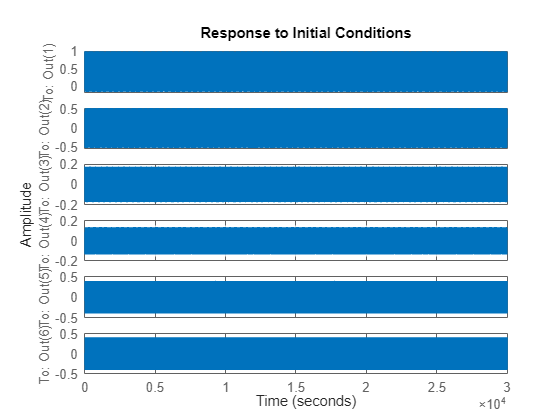


%Plot the output of the initial response of the system 
figure
initial(system, X_Initial);
grid on

% Implementing the LQR Control for visualising to intial conditions
[K, S, Poles] = lqr(system,Q,R);

%To display the output of the LQR Controller Applied to the system along
%with the cost functions 
disp("The gain matrix K is:");

The gain matrix K is:


disp(K);

  100.0000  506.5567  141.5696  -24.6679  182.1430   75.9540




disp("Solution to the associated Ricattie Equation : ")

Solution to the associated Ricattie Equation : 


disp(S);

   1.0e+04 *

    0.0051    0.0123   -0.0002   -0.0229    0.0008   -0.0119
    0.0123    0.0624    0.0216   -0.1164    0.0157   -0.0593
   -0.0002    0.0216    1.0925   -0.0100    0.0199   -0.0698
   -0.0229   -0.1164   -0.0100    2.2329    0.0696    0.0232
    0.0008    0.0157    0.0199    0.0696    0.6536   -0.0097
   -0.0119   -0.0593   -0.0698    0.0232   -0.0097    0.6572



disp("The poles of the system are : ");

The poles of the system are : 


disp(Poles);

  -0.0161 + 0.7276i
  -0.0161 - 0.7276i
  -0.0339 + 1.0422i
  -0.0339 - 1.0422i
  -0.2065 + 0.2023i
  -0.2065 - 0.2023i



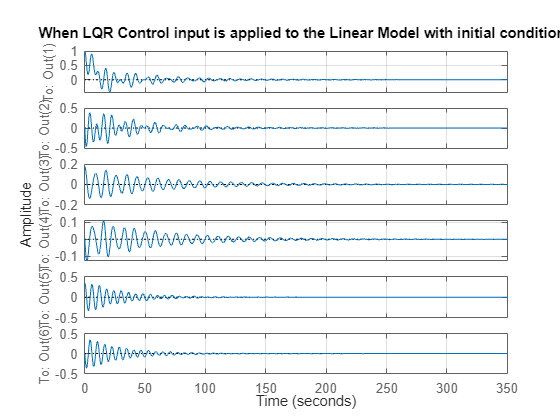


%To obtain state space representation of the closed loop system
system2=ss(A-(B*K), B,C,D);

%Plotting the output of the closed loop system with the chosen initial
%condition
figure
initial(system2,X_Initial);
title("When LQR Control input is applied to the Linear Model with initial conditions");
grid on

%Checking the eigen values of the A-BK matrix to understand stability of
%the system

disp("The Eigen Values of the system are ")

The Eigen Values of the system are 


disp(eig((A)-(B*K)));

  -0.2065 + 0.2023i
  -0.2065 - 0.2023i
  -0.0339 + 1.0422i
  -0.0339 - 1.0422i
  -0.0161 + 0.7276i
  -0.0161 - 0.7276i

